# The kernel trick

This question uses a subset of the iris data - only the sepal widths and sepal lengths for the versicolor and virginica classes:

clear all;
load('binary.mat', 'examples', 'labels');

This question is about training and visualising Support Vector Machines (SVMs) that use the kernel trick to produce nonlinear boundaries. You should use the whole dataset (without splitting) for training. Note that the dataset has already been z-score standardised.

Marks are available for:

- An appropriate call to train an SVM on the whole dataset, using the kernel trick with a Radial Basis Function (RBF) kernel [3 marks]

- An appropriate call to train a *second* SVM on the whole dataset, using the kernel trick with an RBF kernel and a KernelScale of 0.4 [3 marks]

- Extending the `visualiseSVM()` function to give a helpful visualisation of any 2D model trained by the `fitcsvm()` function (the visualisation should at least include the decision boundary and the original training data) [8 marks]

- Using the `visualiseSVM()` function you have developed to produce a visualisation of each of the two SVMs you have trained [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

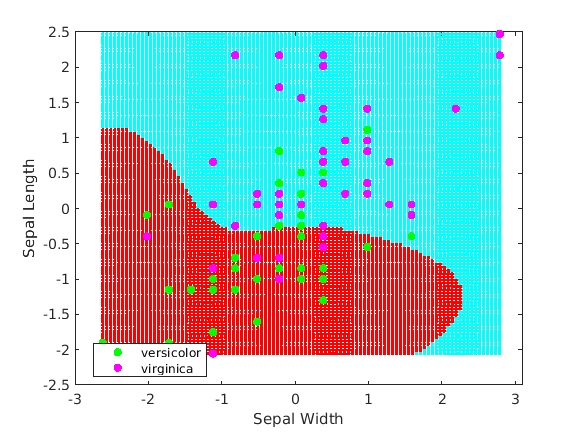

ans = 100×2 table
    sepal_width    sepal_length
    ___________    ____________

      0.98572          1.1134  
      0.98572          0.2082  
       0.6852         0.96253  
       -1.719         -1.1496  
     -0.21638         0.35906  
     -0.21638        -0.84787  
       1.2862         0.05733  
      -1.4185         -2.0548  
     0.084147         0.50993  
      -0.5169         -1.6022  
      -2.6206         -1.9039  
      0.38467        -0.54614  
      -2.0195        -0.39527  
     0.084147         -0.2444  
     0.084147        -0.99874  
       0.6852          0.6608  


ans = 100×1 categorical array
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 


% add as many lines of code as you need below:

%call to train an SVM on the whole dataset, using the kernel trick with a Radial Basis Function (RBF) kernel
m = fitcsvm(examples, labels, 'KernelFunction', 'rbf');

%call to train a second SVM on the whole dataset, using the kernel trick with an RBF kernel and a KernelScale of 0.4
m2 = fitcsvm(examples, labels, 'KernelFunction', 'rbf', 'KernelScale', 0.4);

%produce a visualisation of each of the two SVMs that have been trained
figure(3)
visualiseSVM(m)

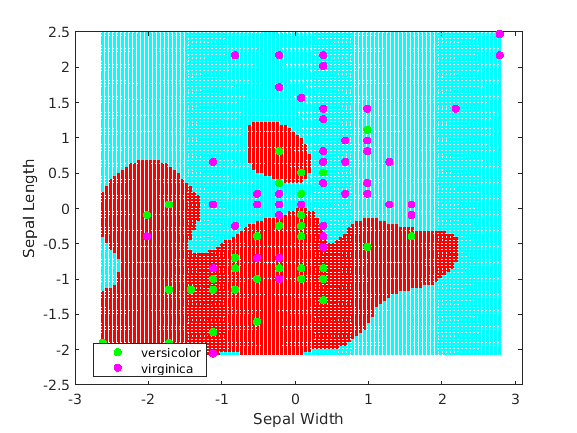

ans = 100×2 table
    sepal_width    sepal_length
    ___________    ____________

      0.98572          1.1134  
      0.98572          0.2082  
       0.6852         0.96253  
       -1.719         -1.1496  
     -0.21638         0.35906  
     -0.21638        -0.84787  
       1.2862         0.05733  
      -1.4185         -2.0548  
     0.084147         0.50993  
      -0.5169         -1.6022  
      -2.6206         -1.9039  
      0.38467        -0.54614  
      -2.0195        -0.39527  
     0.084147         -0.2444  
     0.084147        -0.99874  
       0.6852          0.6608  


ans = 100×1 categorical array
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 


figure(4)
visualiseSVM(m2)

function visualiseSVM(m)

    % Hint: for any model, m, trained with fitcsvm(),
    % you can access the data used to train it with:
    m.X
    m.Y
    
    % Add as many lines of code as you need below:
    x_min = min(m.X{:,1});
    x_max = max(m.X{:,1});
    x_jump = (x_max - x_min) / 100; %find the max, min and jump values for X
    
    y_min = min(m.X{:,2});
    y_max = max(m.X{:,2});
    y_jump = (y_max - y_min) / 100; %find the max, min and jump values for Y
    
    xs = [];
    ys = [];

    for x = x_min:x_jump:x_max %loop for each possible x value
        for y = y_min:y_jump:y_max %loop for each possible x value
            %record the current coordinate
            xs(end+1,1) = x; 
            ys(end+1,1) = y;
        end
    end
    
    predictions = predict(m, [xs ys]); %generate a prediction using model parsed into this function, give all possible x and y values found as parameters

    gscatter(xs, ys, predictions) %plot prediction
    xlabel('Sepal Width')
    ylabel('Sepal Length')

    hold on
    gscatter(m.X{:,1}, m.X{:,2}, m.Y, 'gm') %plot original example values

end